# `MATLAB基础教程`

`作者：To_Fourier`

`创建时间：2020年7月26日20：57`

`修改时间：2020年7月26日23：52`

`个人博客：`[`https://qiuming.blog.csdn.net/`](https://qiuming.blog.csdn.net/)

`GitHub：`[`https://github.com/QiuMingZS`](https://github.com/QiuMingZS)

# `MATLAB概述`

`1.命名：`

`MATLAB = MATrix + LABoratory`

`2.运行平台：`

`Windows, Linux, MacOS`

`3.特点：`

`    1）强大的数值运算功能；`

`    2）强大的图形处理能力；`

`    3）高级但简单的编程环境；`

`    4）丰富的工具箱`

`4.视窗可视化环境`

`    * 标题栏（Title Bar）`

`    * 菜单（Menu）`

`    * 工具栏（ToolBar）`

`    * 视图一：current directory/workspace`

`    * 视图二：command window `

`    * 视图三：command history`

# `Command Window`

`1.命令提示符 >>`

`2.上下左右箭头, Home, End, Delete, Insert`

`3.清空命令行窗口`

clc

`4.清空工作区`

clear

`5.查看帮助`

help sin

sin - 参数的正弦，以弧度为单位

    此 MATLAB 函数 返回 X 的元素的正弦。sin 函数按元素处理数组。该函数同时接受实数和复数输入。 对于 X 的实数值，sin(X) 返回区间 [-1,
    1] 内的实数值。 对于 X 的复数值，sin(X) 返回复数值。

    Y = sin(X)

    另请参阅 <a href="https://localhost:31515/static/help/matlab/ref/asin.html">asin</a>, <a href="https://localhost:31515/static/help/matlab/ref/asind.html">asind</a>, <a href="https://localhost:31515/static/help/matlab/ref/sind.html">sind</a>, <a href="https://localhost:31515/static/help/matlab/ref/sinh.html">sinh</a>, <a href="https://localhost:31515/static/help/matlab/ref/double.sinpi.html">sinpi</a>

    sin 的文档
    名为 sin 的其他函数



`6.查找`

% lookfor sin

`7.查看相关文档`

doc sin

`8.分号取消输出`

a = 5;

`9.续行符`

b = 1 + 2 + 3 + ...
    5 + 6

b =     17


`10.命令之间的逗号`

c = 5, d = 6

c =      5


d =      6


`11.查看MATLAB搜索路径`

path


		MATLABPATH

	C:\Users\44375\Documents\MATLAB
	D:\Matlab_File\CI\gatbx
	D:\Matlab_File\CI\gatbx\DOC
	D:\Matlab_File\CI\gatbx\Test_fns
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\capabilities
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\datafun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\datatypes
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\elfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\elmat
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\funfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\general
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\iofun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\lang
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\matfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\mvm
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\ops
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\polyfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\randfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\sparfun
	C:\Pr

`12.CTRL + C强制终止`

`13.退出MATLAB`

% exit
% quit
% 直接关闭

# `一个简单的例子`

`要求：`

`编写函数文件arith_1.m，任意输入一个正整数，如果是1，直接输出1。`

`否则：如果是偶数，用2除，如果是奇数，用3乘再加1，反复这个过程，直到所得到的数为1，将依次得到的这个数列返回（数列中包括输入的正整数）`

`代码示例：`

arith_1(256)

ans =    256   128    64    32    16     8     4     2     1


# `MATLAB的工作空间`

`  * 当MATLAB启动后，系统会自动建立一个工作空间，这时的工作空间内只包含系统所提供的一些特殊变量，如pi，eps，nan，i等。`

`  * 随着用户的使用，逐渐增加一些用户自己定义的变量。`

`  * 使用who，whos可以查看到当前工作空间所有变量的情况。`

`  * 使用clear可以删除全部或部分工作空间中的变量。`

`  * 关闭MATLAB，释放工作空间，所有变量会被释放。`

# `MATLAB的搜索路径`

path


		MATLABPATH

	C:\Users\44375\Documents\MATLAB
	D:\Matlab_File\CI\gatbx
	D:\Matlab_File\CI\gatbx\DOC
	D:\Matlab_File\CI\gatbx\Test_fns
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\capabilities
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\datafun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\datatypes
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\elfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\elmat
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\funfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\general
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\iofun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\lang
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\matfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\mvm
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\ops
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\polyfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\randfun
	C:\Program Files\Polyspace\R2019b\toolbox\matlab\sparfun
	C:\Pr

`MATLAB遇到一个命令（test）时，其处置过程为： `

`    1.将test视为使用者自定义的变量。 `

`    2.若test不是使用者自定义的变量，将其视为系统定义的常量。 `

`    3.若test不是常量，检查其是否为当前工作目录下的M文件。 `

`    4.若不是，则由搜寻路径寻找是否有test.m的文件。 `

`    5.若在搜寻路径中找不到，则MATLAB会印出错误讯息。`

`    * 处置过程可能因版本不同而略有不同。  `

# `变量`

`MATLAB特殊之处(相较于C语言)：无需进行变量声明。`

`* 遇到新变量名时，自动生成变量，并指定合适的存储空间。`

`* 如变量早已存在，则自动更新。`

## `1.系统特殊变量 `

% ans
1 + 2 + 3 + 4 + 5

ans =     15



% 其他的系统特殊变量
pi

ans =    3.141592653589793


inf

ans =    Inf


eps

ans =      2.220446049250313e-16


nan

ans =    NaN


NaN

ans =    NaN


i

ans =   0.000000000000000 + 1.000000000000000i


j

ans =   0.000000000000000 + 1.000000000000000i


## `2.变量命名规则`

`* 变量名由字母、数字和下划线组成。`

`* 字母间不可留空格且第一个字符必须为字母`

`* 区分大小写。`

`* 变量名的长度上限为n个字符。`

`* 变量名不能为中文；`

`* 系统变量名不要和自定义重名。`

`万一自定义变量名和系统变量名一样结果会怎样？怎么办?`

isvarname  myVarName  

ans = logical
   1


isvarname  7myVarName

ans = logical
   0


## `3.获取当前变量`

`命令行直接键入变量名。`

## `4.变量的精度`

`控制显示精度函数： format`

`控制精度计算的函数：`

`    digits(n):设置缺省的精度；`

`    vpa(S,n):将S表示为n位有效位数的形式。`

x = 0;
for n = 1:82
    x = x + 0.01;
end
x == 0.82  

ans = logical
   0


format long
% x
   
x=0;
for n = 1:82
    x = x + 1;
end
x == 82

ans = logical
   1


## `5.查看变量`

`who：查看当前工作区（workspace）的变量。`

`whos：查看当前变量的详细信息。`

## `6.清除变量`

`clear：清除所有定义过的变量。`

`clear 变量名：清除某个变量。`

## `7.变量的初始化（三种方式）`

`* 用赋值语句初始化变量。`

`* 用input 函数从键盘输入初始化变量。`

in1 = input('enter data:');
in2 = input('enter data:', 's')
in1+in2

`* 从文件读取一个数据。`

## `8.变量的作用域`

`（1）局部变量（Local）：在函数中使用的变量，`

`    只能在函数的范围内使用。`

`（2）全局变量（Global）：在命令文件或工作空间中定义。`

`    用global定义全局变量。`

global  Gvar1 Gvar2 Gvar3

`（3）永久变量（Persistent）：只能在函数文件中定义和使用，只允许定义它的函数存取。只有清除函数或者关闭MATLAB时，才能从内存中清除它们。`

% persistent perVar

`TIPS：尽量不使用全局变量和永久变量！`

# `数据的读写`

`思考：`

`    关闭MATLAB，释放工作空间，所有变量会被释放。`

`    这样会出现什么问题？`

`解决办法：`

`    将工作空间中的变量存储到文件中。`

`    这样，即使退出了MATLAB系统，变量依然存在。需要使用时，将这些变量从文件中读取出来即可`

## `1.save命令`

`功能``：将变量以二进制的方式存储至后缀名为.mat的文档中。`

`格式``：save filename`

`注意事项：`

`1) 存储文件为.mat的二进制mat文档中。`

`2) 若文件名缺省，则自动存储到matlab.mat中。`

`3) 若为save filename x 则只将变量x存储到文件中去。`

`4 ) 若为save filename u w –append 则将变量u，w添加到文件名为filename.mat的文件中。`

`5 ) 若为save filename u w –ascii 则将变量u，w保存为filename的8位ASCII文档。`

`6) 若为save filename u w –ascii -double则将变量u，w保存为filename的16位ASCII文档。`

`Note：ASCII文档特色（使用-ascii后缀）：`

`（1）ASCII文档可以看到文档内容。`

`（2）默认的存储格式是二进制的mat文件。存储ASCII文档必须加-ascii。`

`（3）save  -ascii通常只存为一个变量，原有变量名消失。load载入时，取用文件名为变量名。`

`（4）对于复数，save -ascii后只存实部，虚部抛弃。`

`（5）ASCII文件通常比二进制文件大,二进制文档较小，读取速度快。`

`建议：`

`   尽量使用二进制文件存储MATLAB变量。`

## `2.load命令`

`功能``：读取保存在文件中的变量。`

`格式``：load filename`

`      load filename –ascii`

`      load filename –mat`

`注意事项``：`

`    首先，MATLAB在系统默认路径中自动寻找名称为filename.mat的二进制文件。`

`    其次，若无该文件，则找filename的文件，用ASCII方式载入。`

# `MATLAB的三种控制结构`

`   按照程序设计的观点, 任何算法功能都可以通过`

`程序模块组成的三种基本程序结构的组合来实现:`

`* 顺序结构：程序按程序语句或模块在执行流中的 顺序逐个执行。 `

`* 选择结构：程序按设定的条件实现程序执行流的多路分支。 `

`* 循环结构：程序按给定的条件重复地执行指定的程序段或模块。`

## `1.顺序结构`

a = 0:0.01:2*pi
sin_a = sin(a)
plot(sin_a)

## `2.选择结构`

`* if语句`

clear
n = input('输入n= '); 			
if n >= 90
    r = 'A'
elseif n >= 80
    r = 'B'
elseif n >= 70
    r = 'C'
elseif n >= 60
    r = 'D'
else
    r = 'E'
end

`* switch语句`

clear
n = input('输入n= '); 
lowline = floor(n/10) 
switch lowline
    case {10, 9}
        r = 'A'
    case 8
        r = 'B'
    case 7
        r = 'C'
    case 6
        r = 'D'
    otherwise
        r = 'E'
end

## `3.循环结构`

`* for语句`

clear
sum = 0;
for i = 1:1:100
    sum = sum + i;
end
sum

`* while语句`

clear
sum = 0; 
i = 0;
while i < 100
    i = i + 1;
    sum = sum + i;
end
sum

## `4.break和continue语句`

`* break语句用于立即跳出含该break语句的循环语句。`

`* continue语句用于提前结束当前循环。`

for ii = 1:5
    if ii == 3
        break
    end
    fprintf('ii = %d \n', ii)
end
disp('End of loop!')

for ii = 1:5
    if ii == 3
        continue
    end
    fprintf('ii = %d \n', ii)
end
disp('End of loop!')

## `5.return语句`

`    用于终止当前命令的执行, 在任何地方遇到return时程序立即终止。`

## `6.try-catch语句`

`* 用于实现异常处理机制。`

`* 需要检测的程序必须放在try语句块中执行。`

`* 异常由catch语句捕获并处理。`

clear
N = input('please input N=')
A = magic(3)
try
    A_N=A(N,N)
catch 
    A_end=A(end,end)
end

# `M文件的定义、调用和调试`

`主要类型：`

`* 命令文件（脚本文件）`

`* 函数文件`

`编程原则：`

`* 百分号 % 后面的内容是程序的注释信息。`

`* clear命令用于清除变量，通常用于主程序开头。`

`* 充分利用MATLAB提供的函数来进行运算。`

`* 在语句后输入分号，使中间结果不显示在屏幕上。`

`* 输入少量数据时，可以使用input命令；`

`* 大量的数据输入最好通过子程序完成，在主程序中只需要调用该子程序即可。`

`* 尽量采用主程序调用子程序的方法，使主程序清晰易读，便于维护。`

`* 充分利用调试功能对程序进行调试，有的时候隐含的逻辑错误更不容易发现，危害却更大。`

`* 设置MATLAB的工作路径和当前工作目录，方便操作和运行程序。`

## `1.命令文件（脚本文件）`

`* MATLAB代码按顺序组成的命令序列。`

`* 不接受输入参数和输出参数。`

`* 与MATLAB工作空间共享变量空间。`

## `2.命令文件的调用方法`

`* 在MATLAB命令窗口直接输入命令文件的文件名即可。 `

## `3.Tips:`

`* 命令文件最好保存在当前目录下。 `

`* 命令文件的文件名不要与其他函数/文件重名。 `

`* 命令文件的文件名不要与变量重名。 `

## `4.函数文件`

`* 定义一个函数，需要制定输入参数和输出参数。`

`* 函数文件具有独立的内部变量空间。 `

## `5.函数文件的调用`

`* 输入函数文件的文件名并代入指定的实际参数即可。`

`* MATLAB支持函数的嵌套调用和递归调用。`

## `6.函数文件的格式`

`* 输出参数多于一个时，应使用中括号； `

`* 输入参数多于一个时用逗号隔开； `

`* 函数名与所存的m文件名应同名； `

`* 函数体中可使用错误提示信息：warning（‘message’）。 `

## `7.函数文件与命令文件的区别    `

`* 函数文件用function关键字定义，命令文件则不用；`

`* 函数文件可以传递参数，而命令文件不能传递参数；`

`* 函数文件中定义和使用的是局部变量，只在函数内有效。`

`* 命令文件中的变量都是全局变量，退出命令文件后仍然有效。 `

## `8.函数文件与命令文件的创建   `

`命令文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的命令代码；`

`* 保存文件名为filename.m即完成了命令文件的创建。`

`函数文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的代码，注意第一行必须用function关键字，并定义函数四要素；`

`* 保存文件名为funcname.m，即完成了命令文件的创建。`

`注意，文件名与函数名应同名，最好将M文件放置在MATLAB搜索路径下。`

# `函数基础`

`MATLAB常用的基本数学函数` 

`abs(x)：     纯量的绝对值或向量的长度 `

`sqrt(x)：    开平方 `

`real(z)：    复数z的实部 `

`imag(z)：    复数z的虚部 `

`conj(z)：    复数z的共轭复数 `

`angle(z)：   复数z的相角`

`round(x)：   四舍五入至最近整数 `

`fix(x)：     无论正负，舍去小数至最近整数 `

`floor(x)：   地板函数，即舍去正小数至最近整数 `

`ceil(x)：    天花板函数，即加入正小数至最近整数 `

`rat(x)：     将实数x化为多项分数展开`

`rats(x)：    将实数x化为分数表示 `

`sign(x)：    符号函数 (Signum function)。 `

`rem(x,y)：   求x除以y的馀数 `

`gcd(x,y)：   整数x和y的最大公因数 `

`lcm(x,y)：   整数x和y的最小公倍数 `

`exp(x)：     自然指数 `

`pow2(x)：    2的指数 `

`log(x)：     以e为底的对数，即自然对数 `

`log2(x)：    以2为底的对数 log10(x)：以10为底的对数 `

## `1.匿名函数`

`通常只由一句很简单的声明语句组成。`

`* 匿名函数也可以接受多个输入和输出函数。`

`* 匿名函数的优点是不需要维护一个函数文件。`

`【调用格式】`

`fhandle = @(arglist)expr`

`例题：创建匿名函数myfuncHandle,输入参数为`$x$`，函数完成计算`$x^2 +2x+1$`。`

myfuncHandle  = @(x)(x^2+2*x+1)

myfuncHandle = 包含以下值的 function_handle :
    @(x)(x^2+2*x+1)


myfuncHandle(10)

ans =    121


## `2.主函数和子函数`

`在一个单个的M文件中我们可以定义多个函数。如果多个函数出现在一个文件中，那么第一个定义的（最好与M文件同名的）函数为主函数，其下面定义的的函数称为子函数。`

` 注意：子函数只能被同一文件中的函数调用。`

out1 = mainFunc(5)

out1 =   12.500000000000000


## `3.私有函数`

`指存放在private子目录中的函数。`

`注意``： 私有函数只能由其父目录中的函数调用；在函数调用时优先于其他路径上的函数。`

`调用次序： 子函数 -> 私有函数 -> 搜索路径中的函数。`

## `4.函数的调用`

`函数调用顺序：`

`*  变量`

`*  子函数`

`*  私有函数`

`*  当前目录里的函数`

`*  搜索其他路径`

`调用语法：`

* funcname `参数`1 `参数`2 … `参数`n

* funcname(`参数`1 `参数`2 … `参数`n)

* output = funcname(`参数`1`，参数`2`，`…,`参数`n)

* [out1,out2,…,outn] = funcname(`参数`1`，参数`2`，`…,`参数`n)

## `5.函数的参数传递`

`* 按值传递机制：当一个函数调用发生时，MATLAB 将会复制实参生成一个副本，然后把它们传递给函数。这次复制是非常重要的，因为它意味着虽然函数修改了输入参数，但它并没有影响到调用者的原值。`

`* 防止了因函数修改变量而导致的严重错误。`

a = 2; 
b = 6;
fprintf('Before sample: a = %f, b = %f\n', a, b);

Before sample: a = 2.000000, b = 6.000000


out = sample(a, b);

In Sample, before compute: a = 2.000000, b = 6.000000 
In Sample, after compute: a = 10.000000, b = 60.000000


fprintf('After sample: a = %f, b = %f\n',a,b);

After sample: a = 2.000000, b = 6.000000


fprintf('After sample: out = %f \n', out);

After sample: out = 10.000000 
After sample: out = 60.000000 


## 6.`函数的参数可调性`

* MATLAB`在函数调用上有一个``特色``，函数所传递参数数目的``可调性``，即`

`  传递的参数的个数可以任意。`

**MATLAB**`提供了两对永久变量：`

* nargin`和`varargin`：用于检查被调用函数的输入参数数目`,`检查函数体内的被调用时的输入参数的值。`

* nargout`和`varargout`：用于检查被调用函数的输出参数的个数和每个输出参数`

x =   5.000000000000000 + 0.000000000000000i  4.997532801828658 + 0.157053795390641i  4.990133642141358 + 0.313952597646567i  4.977809823015400 + 0.470541566592572i  4.960573506572389 + 0.626666167821521i  4.938441702975689 + 0.782172325201154i  4.911436253643443 + 0.936906572928623i  4.879583809693737 + 1.090716206982713i  4.842915805643155 + 1.243449435824274i  4.801468428384715 + 1.394955530196146i  4.755282581475767 + 1.545084971874737i  4.704403844771127 + 1.693689601226457i  4.648882429441256 + 1.840622763423390i  4.588773128419906 + 1.985739453173903i  4.524135262330097 + 2.128896457825364i  4.455032620941839 + 2.269952498697734i  4.381533400219318 + 2.408768370508577i  4.303710135019719 + 2.545207078751857i  4.221639627510076 + 2.679133974894983i  4.135402871372809 + 2.810416889260653i  4.045084971874737 + 2.938926261462366i  3.950775061878452 + 3.064535268264883i  3.852566213878946 + 3.187119948743449i  3.750555348152298 + 3.306559326618259i  3.644843137107058 + 3.422735529643

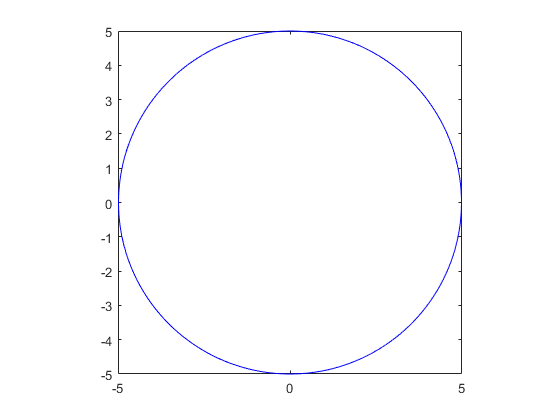

area = circle(5, 'b')

## `7.程序设计的基本步骤`

`（1）清晰地陈述你要解决的问题`

`（2）确定程序的输入输出`

`（3）为你的程序设计算法`

`（4）将算法转化为程序语言`

`（5）调试程序`

# 函数脚本

% 脚本名称：arith_1.m
% 脚本功能：任意输入一个正整数，如果是偶数，用2除
%                              如果是奇数，用3乘再加1
%           反复重复这个过程，直到得到的数为1
%           将依次得到这个数的数列返回
% 脚本作者：左手Python右手R
% 创建时间：2018年07月12日19:32
% 修改时间：

function y = arith_1(x)
    % 健壮性判断
    if round(x) ~= x
        error('Please enter an integer!');
    end
    
    k = 1;                  % 赋序列初始索引
    y(k) = x;               % 输入
    while (x~=1) 
        k = k + 1;          % 索引递增
        if rem(x, 2) == 0   % 求余
            x = x/2;        % 执行偶数对应操作
            y(k) = x;
        else 
            x = x*3 + 1;    % 执行奇数对应操作
            y(k) = x;
        end
    end
end

function y = mainFunc(x)
    y = x*subFunc(x);
end

function u = subFunc(w)
    u = w/2;
end

function [y] = sin_cos(x)
%SIN_COS a small calculation
%   cal cos then sin and return
%   input: x
%   output: y

y = sin(cos(x));

end

function out = sample(a, b)
fprintf('In Sample, before compute: a = %f, b = %f \n', a, b);
a = b + 2*a;
b = a * b;
out = [a  b];
fprintf('In Sample, after compute: a = %f, b = %f\n', a, b);
end

function s = circle(r, c)
%CIRCLE plot a circle of radii r, with color c

% input: r, radius
%        c, color
% output: s, area
if nargin == 1
    c = 'b';
end
clf
t = 0:pi/100:2*pi;
x = r*exp(i*t)
if nargout == 0
    plot(x, c)
else
    s = pi*r*r;
    fill(real(x), imag(x), c)    
end
axis('square')
end